syms t1 t2 t3 t4 t5 t6 real;

% Read angles from CSV file
anglesList = readtable('mazeangles.csv');

% Convert table to matrix and convert to radians
anglesList_rad = deg2rad(table2array(anglesList));

% Load the robot from the URDF file
robot = importrobot("E:\ras\project\project\TEST_files\Final_files\my_pro600.urdf");
figure(1);
config = homeConfiguration(robot);
show(robot, config);

% Set up the figure
view(-100, 90);
axis([-1 1 -1 1 0 1.5]);
grid on;
hold on; % To retain plots
camzoom(1.20);
h = light('Style', 'infinite', 'Position', [0.2, 0.7, 0.9], 'Color', [1, 1, 1]);
p = light('Style', 'local', 'Position', [-0.4, -0.7, -0.9], 'Color', [1, 1, 1]);

% Animation parameters
totalDuration = 0.1;  % 5 seconds for each movement
frameRate = 60;  % 60 frames per second
nSteps = totalDuration * frameRate;

% Initialize the path array for storing end-effector positions
path = [];

% Function to compute the end-effector position
function pos = getEndEffectorPosition(robot, config)
    tform = getTransform(robot, config, 'link6', 'base_link'); % Adjust 'tool0' if the end-effector link is named differently
    pos = tform(1:3, 4); % Extract the XYZ position
end

% Function to animate movement
function path = animateMovement(robot, startAngles, endAngles, nSteps, frameRate, path)
    for i = 0:nSteps
        alpha = i / nSteps;
        config = homeConfiguration(robot); % Start with a valid configuration structure
        for j = 1:numel(config)
            config(j).JointPosition = (1-alpha) * startAngles(j) + alpha * endAngles(j);
        end
        show(robot, config, 'PreservePlot', false);
        % Compute the end-effector position
        pos = getEndEffectorPosition(robot, config);
        path = [path; pos']; % Append the position to the path
        % Plot the path
        plot3(path(:, 1), path(:, 2), path(:, 3), 'r-', 'LineWidth', 2);
        drawnow;
        pause(1 / frameRate);
    end
end

% Animate through all angle sets
disp('Starting simulation...');

Starting simulation...


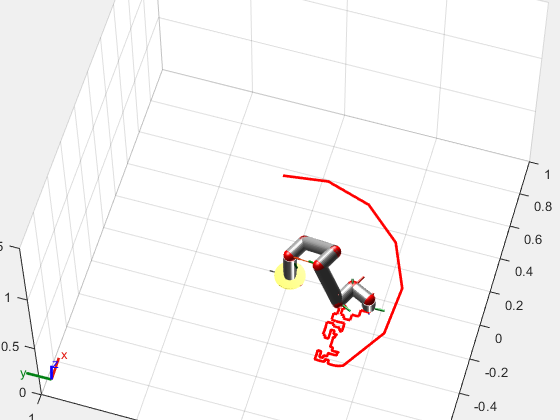

Moving to position 1...
Moving to position 2...
Moving to position 3...
Moving to position 4...
Moving to position 5...
Moving to position 6...
Moving to position 7...
Moving to position 8...
Moving to position 9...
Moving to position 10...
Moving to position 11...
Moving to position 12...
Moving to position 13...
Moving to position 14...
Moving to position 15...
Moving to position 16...
Moving to position 17...
Moving to position 18...
Moving to position 19...
Moving to position 20...
Moving to position 21...
Moving to position 22...
Moving to position 23...
Moving to position 24...
Moving to position 25...
Moving to position 26...
Moving to position 27...
Moving to position 28...
Moving to position 29...
Moving to position 30...
Moving to position 31...
Moving to position 32...
Moving to position 33...
Moving to position 34...
Moving to position 35...
Moving to position 36...
Moving to position 37...
Moving to position 38...
Moving to position 39...
Moving to position 40...
Moving to

currentAngles = zeros(1, 6); % Start at home position [0,0,0,0,0,0]
for k = 1:size(anglesList_rad, 1)
    targetAngles = anglesList_rad(k, :);
    disp(['Moving to position ', num2str(k), '...']);
    path = animateMovement(robot, currentAngles, targetAngles, nSteps, frameRate, path);
    currentAngles = targetAngles; % Update current angles
    pause(2); % Pause between movements
end


% Remove the robot and retain the path
disp('Removing the robot and retaining the path...');

Removing the robot and retaining the path...


cla; % Clear the axes (removes robot and lights)
plot3(path(:, 1), path(:, 2), path(:, 3), 'r-', 'LineWidth', 2); % Re-plot the path
axis([-1 1 -1 1 0 1.5]);
grid on;
view(-100, 90);
title('Robot Path');
xlabel('X');
ylabel('Y');
zlabel('Z');

% Save the final path image
disp('Saving the final path image...');

Saving the final path image...


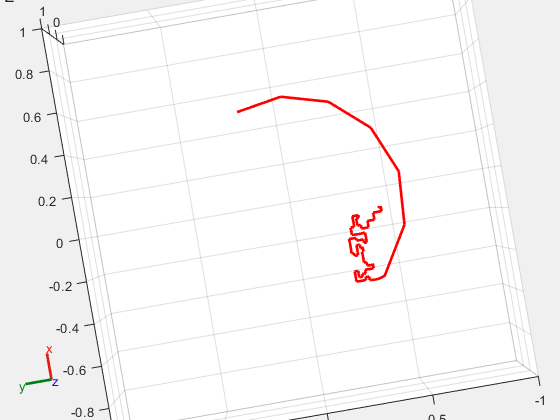

saveas(gcf, 'robot_path_only.png');

disp('Simulation complete. Path image saved as "robot_path_only.png".');

Simulation complete. Path image saved as "robot_path_only.png".
